# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all
close all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)
plotnam = "2-Schlogl"

model_name = "Selkov"
plotnam = "Selkov"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr
hc_net
i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;

#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')

#### Sample space uniform and plot

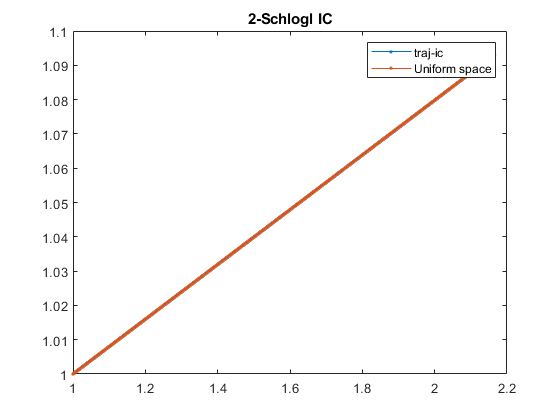

%Space uniform sampling
traj_pts = 500;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);
%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1);

%Initialize arrays for saving and delta_x_s
Initialize_descender

S_arr =    0.016810810232826



%Save data to file in the data folder
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'straight_'+string(traj_pts)+'_'+string(date)+'_unfiltered.mat'

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_500_23-Aug-2022_unfiltered.mat"

%Save data to file in the data folder (for spiral)
%savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
%+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

save_plot_name_root = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+string(date)+'unfiltered'

save_plot_name_root = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered"

## Actual descent

%Actual descender
eps_ic = 1; eps = eps_ic; eps_min = 0.005;     %Initial and least step size
delta_S = 10; err_thresh = 10^(-1); 
f0_max = 40; f0_step = 0.1; f0_init = f0;
eps_S_thresh = 10^(-7); delta_S_thresh = 5*10^(-6);
iter_max = 10; iter = 1; a_min=100; a_thresh = 0.001;
delta_S_thresh_eps = 10^(-7);time_uniform_f = 45;
%time_uniform_f = 35 for Schlogl

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_4.png"

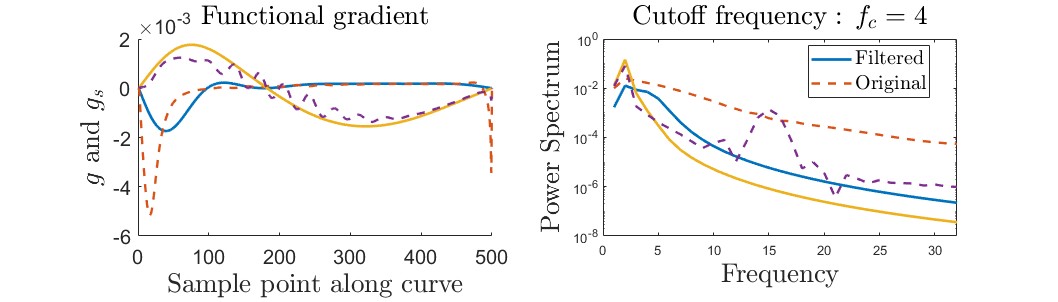

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_4.png"

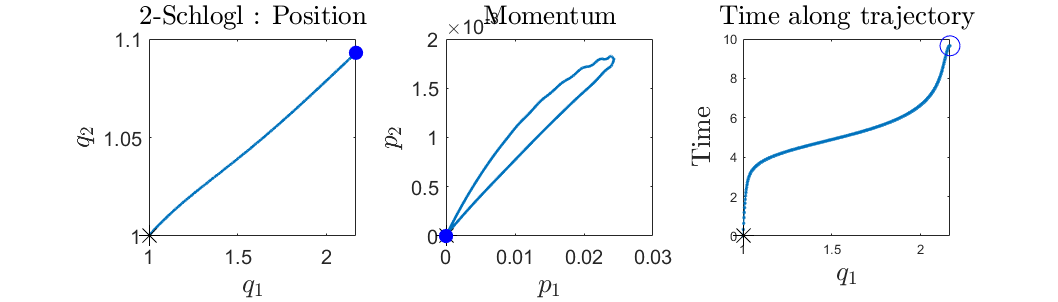

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_6.png"

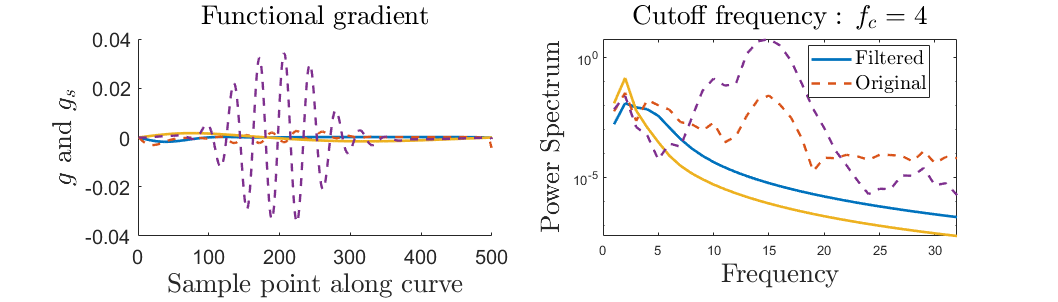

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_6.png"

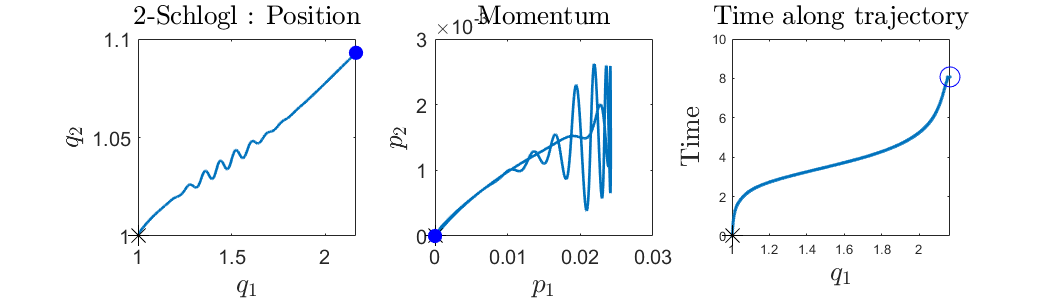

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_8.png"

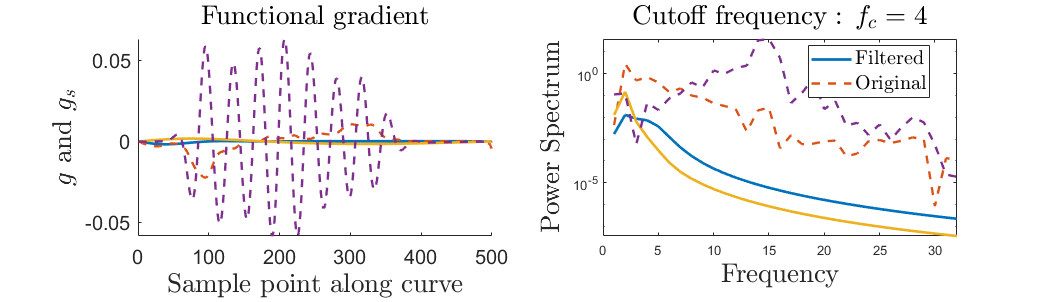

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_8.png"

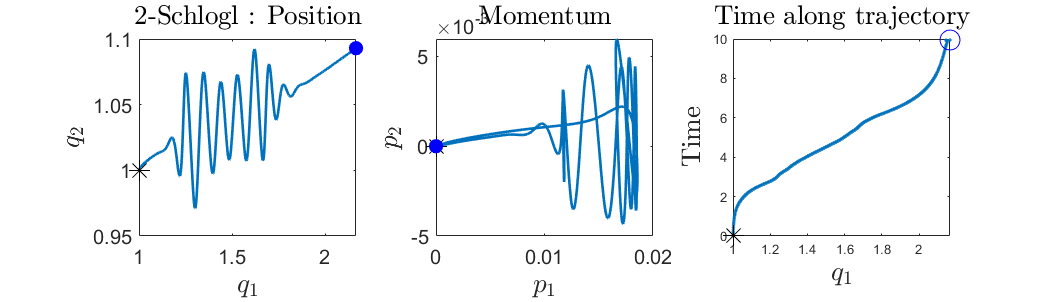

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_10.png"

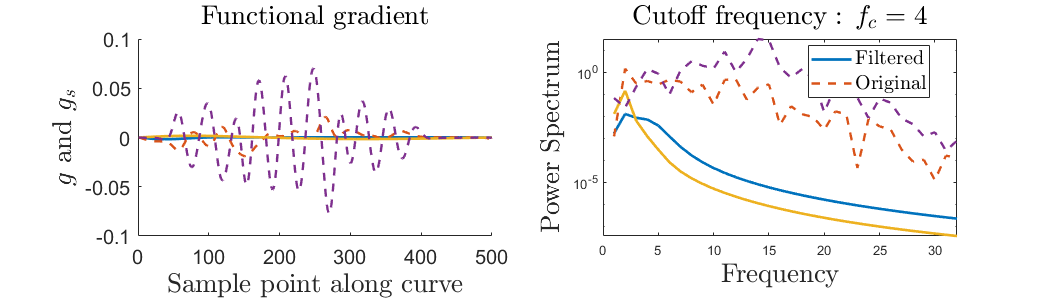

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_10.png"

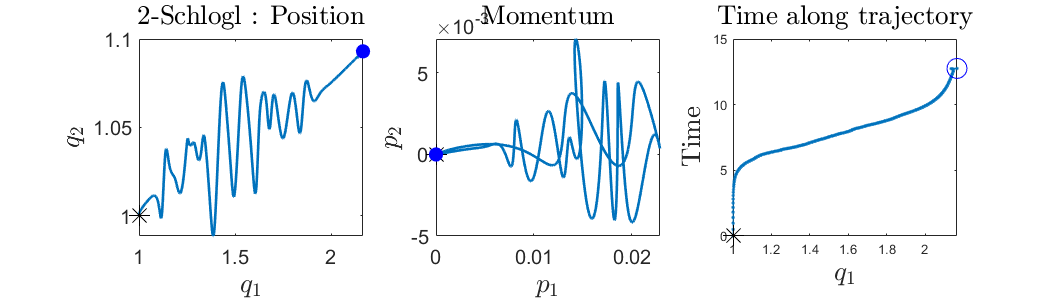

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_12.png"

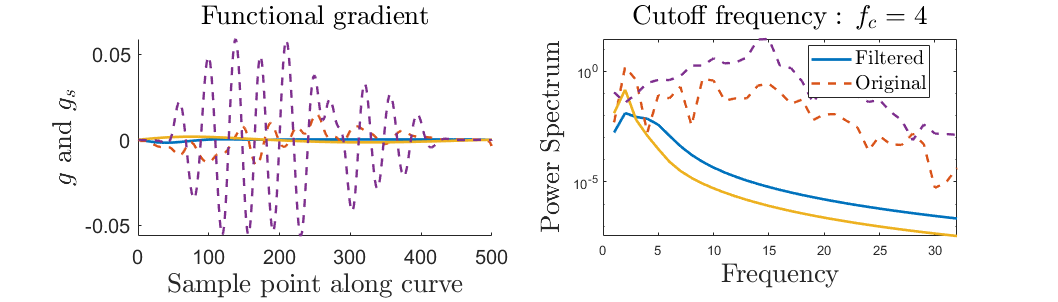

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_12.png"

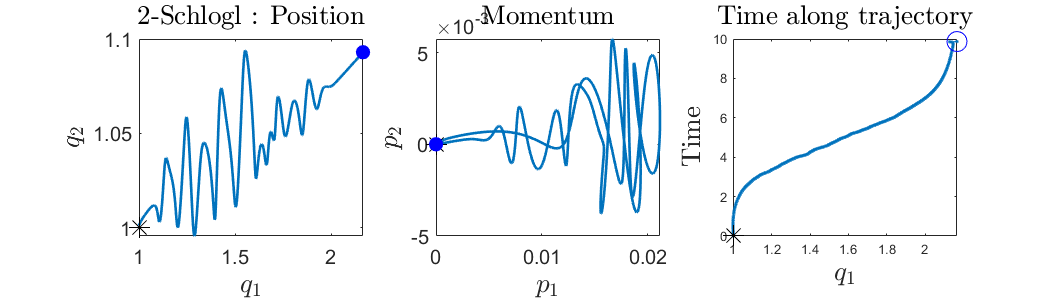

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_14.png"

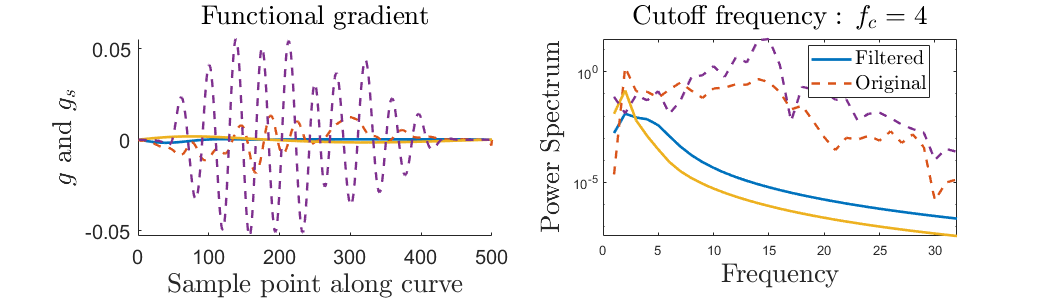

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_14.png"

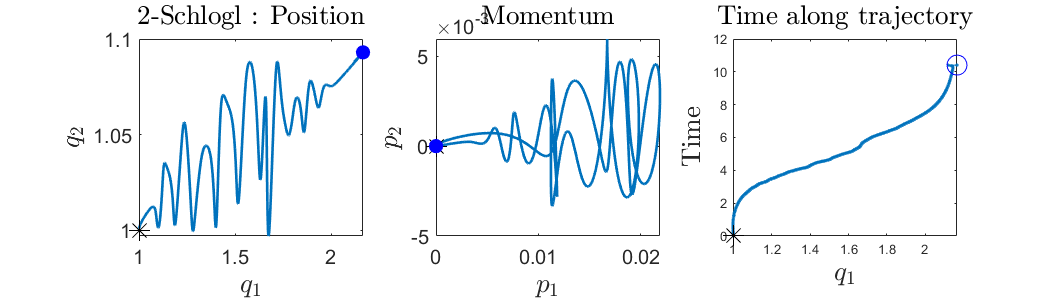

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_16.png"

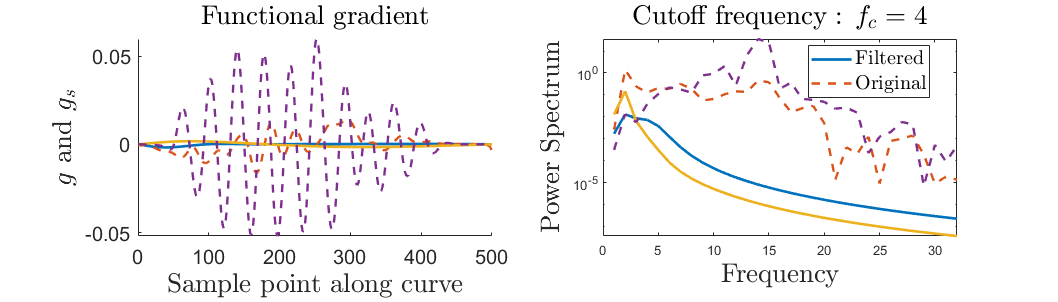

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_16.png"

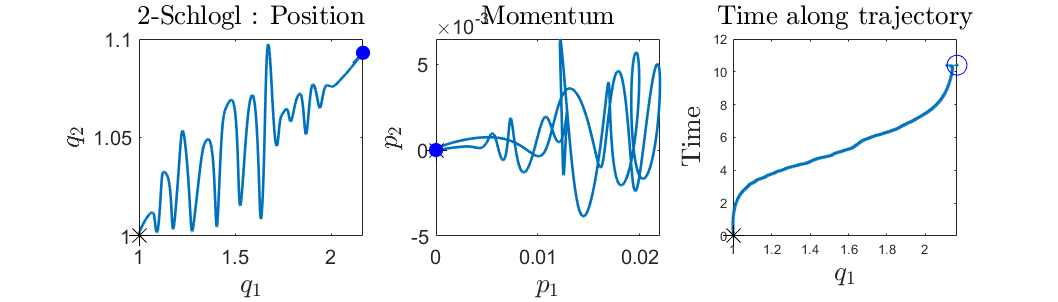

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_18.png"

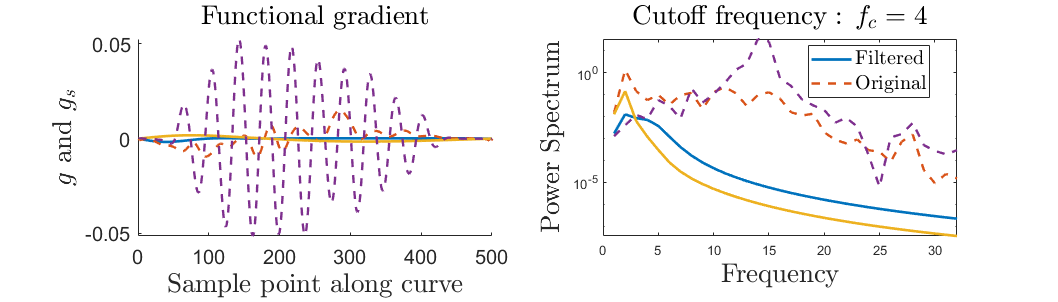

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_18.png"

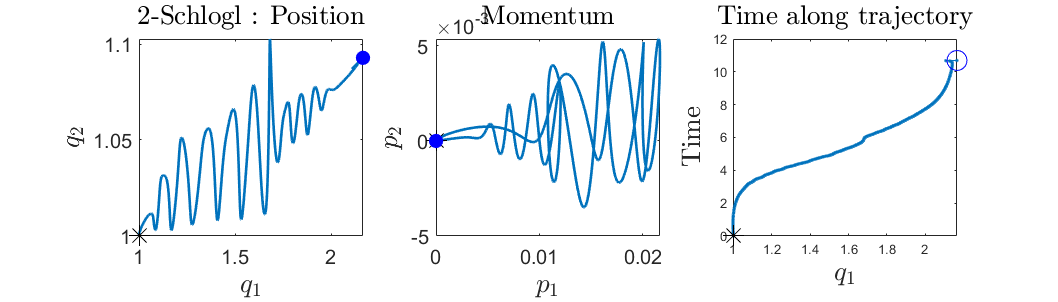

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_20.png"

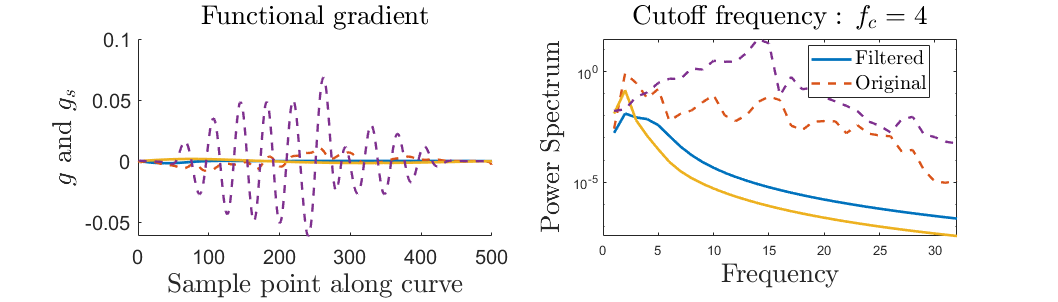

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_PS_traj_20.png"

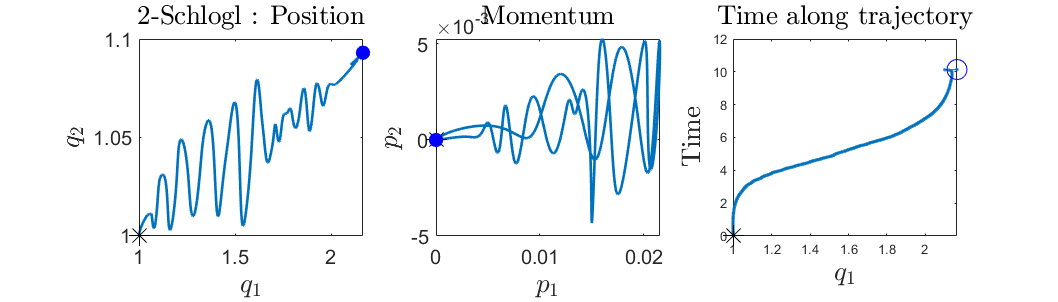

save_plot_name = "Plots/Schlogl_1_2_1_2_500_23-Aug-2022unfiltered_deltax_22.png"

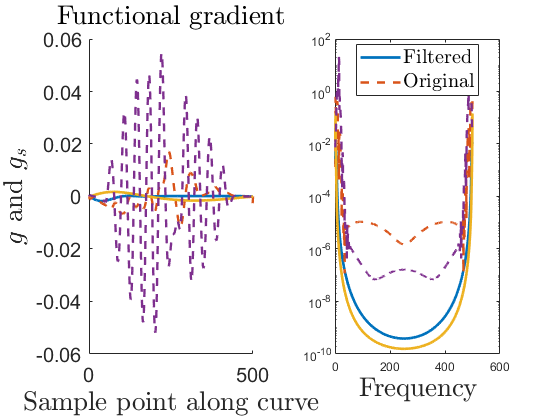

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in ylabel (line 65)
    h = get(ax,'YLabel');

Error in debugging_deltax_plots (line 36)
    ylabel('Power Spectru

format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max && a_min>a_thresh
    iter = iter + 1;
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);
    traj = PS_traj(:,1:num_spec) + delta_x;

    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,2)==0
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png';
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png';
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
        %save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter)+'.png';
        %a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,0,plotnam)
    end

    
end

format short

save_plot_name

iter = 30;
traj_pts = 500;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
figure()
plot(t_traj)
traj = PS_traj(:,1:2);
traj = time_uniform_filter(traj,t_traj,traj_pts,40);

[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

%delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,20);
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

figure()
plot(t_traj)

#### Look for a settiing which works

format long
f0 = 6; eps_min = 0.001;eps = 0.5;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

traj_pts_new = 3000;
traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
%[traj,len_curve_prime] = space_uniform_sampling(traj_n_s,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

f0 = 6; eps_min = 0.03;eps = 0.1;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

iter = 35;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
save_plot_name = save_plot_name_root + '_' + string(iter) + '_HamEoM';
a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)


debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

plot_everything_1

f0 = 5; delta_x_s =  smooth_traj_butter(delta_x,f0); 

choose_iter = iter-1; f0 = 2;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,choose_iter);
delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,choose_iter);


iter_max = 24;f0 = 0.5;eps = 0.0001;

iter_max = 57;f0 = 2;

traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,100);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
figure()
plot(PS_traj(:,3),PS_traj(:,4))

traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,45);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
figure()
plot(PS_traj(:,3),PS_traj(:,4))

figure()
semilogy(abs(fft(traj_n_s)).^2)
hold on
semilogy(abs(fft(traj)).^2,'--')
hold off
xlim([0 20])

figure()
plot(traj_pt_arr)

figure()
plot(PS_traj(end-200:end,3),PS_traj(end-200:end,4))
hold on
plot(PS_traj(1:5,3),PS_traj(1:5,4),'--')
hold off

size(time_arr)
traj_pt_arr;

idx = 40;
cum_traj = [0 ;cumsum(traj_pt_arr)];
time_arr(cum_traj(idx-1)+1:cum_traj(idx),:)

figure()
plot(t_traj,'.')

num_smooth = 45;
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

num_smooth = 45;
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

figure()
plot(PS_traj(end-10:end,3:4),'.-')

figure()
plot(delta_x(end-10:end,:),'.-')
hold on
plot(delta_x(1:10,:),'.--')
hold off

traj_pts_new = traj_pts+1000;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,35);


%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj'+string(iter)+'.png'
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

savenam


delta_x(3,:)

[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);


figure()
plot(traj(1:100:end,1),traj(1:100:end,2),'.')

traj_pts_new = traj_pts;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj_n_s,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

figure()
plot(traj_n_s(:,1),traj_n_s(:,2))
hold on
plot(traj(:,1),traj(:,2),'--')
hold off
figure()
plot(PS_traj(:,3),PS_traj(:,4))  